# 符号变量的定义与运算

clear; clc

简单符号变量的创建：syms

syms x; % 定义x为符号变量
syms a b c d; % 定义多个符号变量, 用空格分隔
x % 符号变量

$$x = x$$

符号方程的创建:

syms a x; % 声明符号变量
y = a * x + x^2; % 表达式创建
% y = str2sym('a*x+x^2'); % 字符串 to sym, 字符串创建符号方程
% latex: x^2 +a\,x
y % 在实时脚本中可以转换为latex代码,方便复制到word和axmath中

$$y = x^{2}+a\,x$$

符号矩阵

syms alpha;
M = [
    cos(alpha) -sin(alpha); % ;表示该行结束,到下一行
    sin(alpha) cos(alpha)
] % 得到latex代码:

$$M = \left(\begin{array}{cc} \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

## 简单运算

syms a b c d e;
% 符号变量可以当成普通的变量进行加减乘除运算
y = a + b

$$y = a+b$$

x = c - d

$$x = c-d$$

y1 = x * y

$$y1 = \left(a+b\right)\,\left(c-d\right)$$

y2 = y1/y

$$y2 = c-d$$

y3 = y1^3

$$y3 = {\left(a+b\right)}^{3}\,{\left(c-d\right)}^{3}$$

y4 = sqrt(y3)

$$y4 = \sqrt{{\left(a+b\right)}^{3}\,{\left(c-d\right)}^{3}}$$

y5 = exp(y4)

$$y5 = {\mathrm{e}}^{\sqrt{{\left(a+b\right)}^{3}\,{\left(c-d\right)}^{3}}}$$

% 可见, 符号表达式逐渐复杂,那么有没有整理表达式的函数呢

## 符号表达式的整理

clear; clc

### simplify(): 化简符号表达式

% 生成符号表达式
syms a;
y=(cot(a/2)-tan(a/2))*(1+tan(a)*tan(a/2))

$$y = \left(\cot\left(\frac{a}{2}\right)-\tan\left(\frac{a}{2}\right)\right)\,\left(\tan\left(\frac{a}{2}\right)\,\tan\left(a\right)+1\right)$$

% simplify()函数, 用于简化符号表达式
simplify(y) % 得到的结果是整理后的

$$ans = \frac{2}{\sin\left(a\right)}$$

### factor(): 因式分解

factor(15) % 对常数进行因式分解

ans =      3     5


syms m n x; 
y = -24*m^2*x-16*n^2*x

$$y = -24\,x\,m^{2}-16\,x\,n^{2}$$

result = factor(y); % 对上面的符号表达式进行因式分解
% 得到的分解, 用行向量表示(空格分隔)
result

$$result = \left(\begin{array}{ccc} -8 & x & 3\,m^{2}+2\,n^{2} \end{array}\right)$$

y1=m^3-n^3

$$y1 = m^{3}-n^{3}$$

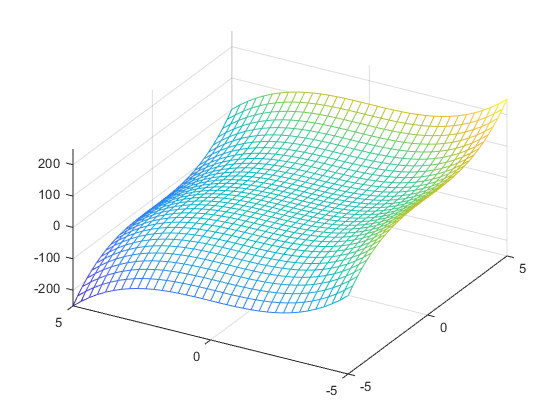

% 图像:
fmesh(y1)
view([-60 41]) % 特定角度的显示

factor(y1) % 因式分解

$$ans = \left(\begin{array}{cc} m-n & m^{2}+m\,n+n^{2} \end{array}\right)$$

### expand(): 多项式展开

syms a x;
y = a * (x^2 - a)^2 + (x - 2)

$$y = x+a\,{\left(a-x^{2}\right)}^{2}-2$$

expand(y) % 展开(能做的运算全做)

$$ans = a^{3}-2\,a^{2}\,x^{2}+a\,x^{4}+x-2$$

### collect(): 多项式合并

syms x y;
z = (x+y)^2*y+5*y*x-2*x^3

$$z = 5\,x\,y+y\,{\left(x+y\right)}^{2}-2\,x^{3}$$

disp("展开:expand(z):"); disp(expand(z));

展开:expand(z):


$$-2\,x^{3}+x^{2}\,y+2\,x\,y^{2}+5\,x\,y+y^{3}$$

% 合并: collect()
disp("合并后:collect(z):"); disp(collect(z));

合并后:collect(z):


$$-2\,x^{3}+y\,x^{2}+\left(2\,y^{2}+5\,y\right)\,x+y^{3}$$

% 以x, y分别进行合并
collect(z,x) % 以x合并

$$ans = -2\,x^{3}+y\,x^{2}+\left(2\,y^{2}+5\,y\right)\,x+y^{3}$$

collect(z,y) % 对y进行合并

$$ans = y^{3}+\left(2\,x\right)\,y^{2}+\left(x^{2}+5\,x\right)\,y-2\,x^{3}$$

### numden(): 计算分子分母

% [分子 分母] = numden(符号表达式) 
% 注意括号中的变量必须是符号变量
% numden(2.5) 就会报错, 所以我们需要double -> syms, 使用sym函数强转成符号变量
[z1 z2] = numden(sym(2.5));
disp("分子:"); disp(z1);

分子:


$$5$$

disp("分母:"); disp(z2)

分母:


$$2$$

复杂一点的表达式:

syms x y;
z = 1 / x * y + x / (x^2 - 2*y)

$$z = \frac{y}{x}-\frac{x}{2\,y-x^{2}}$$

[z1 z2] = numden(z) % 计算得到分子分母

$$z1 = -x^{2}\,y-x^{2}+2\,y^{2}$$

$$z2 = x\,\left(2\,y-x^{2}\right)$$

## 最后一点

syms x y
M = (1/x*y+x/(x^2-2*y)-x^2/(3+y)^2)^2;
expand(M) % 展开

$$ans = \frac{y^{2}}{x^{2}}+\frac{x^{4}}{y^{4}+12\,y^{3}+54\,y^{2}+108\,y+81}+\frac{2\,x^{3}}{-x^{2}\,y^{2}-6\,x^{2}\,y-9\,x^{2}+2\,y^{3}+12\,y^{2}+18\,y}-\frac{2\,y}{2\,y-x^{2}}+\frac{x^{2}}{x^{4}-4\,x^{2}\,y+4\,y^{2}}-\frac{2\,x\,y}{y^{2}+6\,y+9}$$

% mupad % 2020b版本中, MATLAB已经remove了mupad, 可以使用实时脚本来代替它
% 可以将符号表达式显示的更加易于人类阅读.
% 并且我们在实时脚本中, 也可以复制函数为latex代码.




































